clear, clc;


## Parameters

%Student ID 2024161152
A1 = 2;
A2= 5;
L1 = 20+A1/0.5; % Length of the first medium in meters
L2 = 15+A2/0.5; % Length of the second medium in meters
c1 = 1500.0+10.0*A1-A2; % Speed of sound in the first medium in m/s
c2 = (1800.0+20.0*A2*A1)*(1+0.02*1i*(2+sqrt(A1))); % Speed of sound in the second medium in m/s
rho = 1000; % Density in kg/m^3
f = 500.0+A2*20.0+A1; % Excitation frequency in Hz
w = 2 * pi * f; % Angular frequency

% Total length and number of points
L = L1 + L2;
% Discretizaion
npts = 200; % Total number of discretization points
ne = (npts - 1);
dx = L / ne; % Spacing between points
x = 0:dx:L; % Point coordinates and L = dx*(npts-1)

## Boundary Conditions

p = 1.0; %pressure at x = 0 drichlet condition


% Initialize system matrix and independent term
A = zeros(npts);
B = zeros(npts, 1);

% Apply boundary conditions
A(1, 1) = 1; % 
B(1) = 1; % Dirichlet condition at the left




## Finite difference


% Fill the system matrix for each medium

for ii = 2:npts-1

    if x(ii) < L1 % In the first medium
        c = c1;
        K_1 = w / c1; % Wave number for the current medium
        K = K_1;
        k1 = 1/dx^2;
        k2 = -2/dx^2 + K^2;
        k3 = 1/dx^2;
        A(ii, ii-1:ii+1) = [k1, k2, k3];

    elseif x(ii) == L1 % at common node

        K_m = 1
        k1 = 1/dx;
        k2 = -2/dx;
        k3 = 1/dx;
        A(ii, ii-1:ii+1) = K_m * [k1, k2, k3];

    elseif x(ii) > L1 && x(ii)<=L  % In the second medium

        K_2 = w / c2; % Wave number for the current medium
        K= K_2;
        k1 = 1/dx^2;
        k2 = -2/dx^2 + K^2;
        k3 = 1/dx^2;
        A(ii, ii-1:ii+1) = [k1, k2, k3];

    end



end

% z = rho * c2;  % Acoustic impedance for the second medium (Robin condition)
% impedance_coeff = -1 - 2 * 1i * w * rho / z;
% A(end, end-1:end) = impedance_coeff * [-1/dx, 1/dx];
% B(end) = 0; commented because weird results so separately putting the
% conditions on last two rows


Z = rho * c2; % Impedance condition for fluid M2
A(end, end-1) = -Z/(1i*rho*w*dx);
A(end, end) = (1 + Z/(1i*rho*w*dx));

## Solve the system

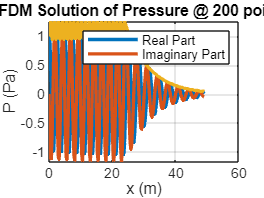


P = A \ B;

% Plot the solution
figure;
plot(x, real(P), x, imag(P),x, abs(P), 'LineWidth', 2);
grid on;
xlabel('x (m)');
ylabel('P (Pa)');
legend('Real', 'Imaginary','absoltute');
grid on;
xlabel('x (m)');
ylabel('P (Pa)');
legend('Real Part', 'Imaginary Part');
title('FDM Solution of Pressure @ 200 points');

## Analytical solution

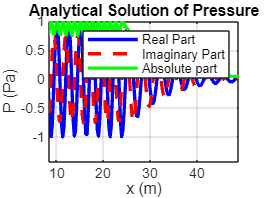

P_analytic = solution_1D(f, c1, c2, L1, L2, x);  % Analytical solution

% Plot the real and imaginary parts of the analytical solution
figure(2);
plot(linspace(0, L1 + L2, npts), real(P_analytic), 'b-', 'LineWidth', 2);  % Real part
hold on;
plot(linspace(0, L1 + L2, npts), imag(P_analytic), 'r--', 'LineWidth', 2);  % Imaginary part
plot(linspace(0, L1 + L2, npts), abs(P_analytic), 'g', 'LineWidth', 2);  % Imaginary part
hold off;

grid on;
xlabel('x (m)');
ylabel('P (Pa)');
legend('Real Part', 'Imaginary Part','Absolute part');
title('Analytical Solution of Pressure');

xlim([8.4 48.9])
ylim([-1.43 1.00])

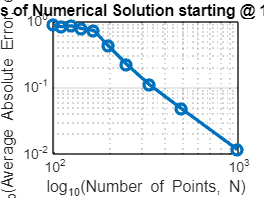

num_discretizations = 10;
epsilon_fdm=zeros(num_discretizations,1);
npoints=zeros(num_discretizations,1);
num_discretizations = 10;
element_sizes = linspace(0.5, 0.05, num_discretizations); % From 1.0 m to 0.1 m

for n=1:num_discretizations
    dx = element_sizes(n); % Current element size
    N = round(L / dx); % Number of nodes
    P_FD = Helmholtz_Finite_Difference(N,L1,L2,c1,c2,f);
    P_analytical = solution_1D(f,c1,c2,L1,L2,linspace(0,L,N));
    epsilon_fdm(n)=(sum(abs(P_analytical-P_FD)))/(N);
    npoints(n)=N;
    

end

figure(3);
loglog(npoints, epsilon_fdm, 'o-', 'LineWidth', 2);
grid on;
xlabel('log_{10}(Number of Points, N)');
ylabel('log_{10}(Average Absolute Error, epsilon)');
title('Convergence Analysis of Numerical Solution starting @ 100 points and increasing');



% 

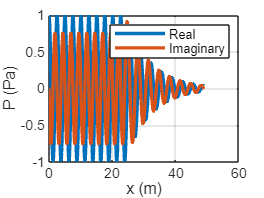

% 
[min_value, min_index] = min(epsilon_fdm);

P = Helmholtz_Finite_Difference(npoints(min_index), L1, L2, c1, c2, f);

% Ensure that the x-coordinates match the length of P
x = linspace(0, L, npoints(min_index)); % Use the optimal grid size

% Plot the solution
figure;
plot(x, real(P), x, imag(P), 'LineWidth', 2);
grid on;
xlabel('x (m)');
ylabel('P (Pa)');
legend('Real', 'Imaginary');

% 
% 

